% code for plot results of Widefield imaging, which contain functions listed
% below
% Align neural activity of different trails by behavior events
% plot aligned neural activity of each trial (line + heatmap)
% plot activity correlation of each brain region
% plot neural activity sequence averaged by specific timebin
% plot neural activity averaged by specific behavior

% cut and align the neural activity based on behavior bout written by NY
clear all;
close all;
clc;

CompNum = 40;

Initial = 'KM';
Animal = 'Tlx75';
Date = '230709';
totalBlock = 2;
Key = 'max';
signal = 'df_f'; % 'df_f' or 'raw'

working_directory = '/home/naohiro/Desktop/Yoshida_analysis/Wide-field-calcium-imaging/';

fps = 40;
% make sure the order of the rows in the table should line up with the order of the names in the imaging file
filename = [working_directory Date filesep Initial '_' Animal filesep 'BehaviorRecord.csv'];
before = 1000;
after = 4000;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% load neural activity data
cd([working_directory Date filesep Initial '_' Animal filesep 'ICA' filesep 'ICA_40']);
if strcmp(signal, 'df_f')
    load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],'RecICA_Temp','-mat');
elseif strcmp(signal, 'raw')
    load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key '_raw'],'RecICA_Temp','-mat');
end

% load behavior data
opts = detectImportOptions(filename);
opts.VariableNamesLine = 1;
timepoints_table = readtable(filename, opts); %[working_directory Date filesep Initial '_' Animal filesep 'BehaviorRecord.csv'],'NumHeaderLines',1);


% cut and align each data
% how to deal with data which do not contain enough before or after
% timepoints
% colum 23: lift-1sec (ms)
RecICA_cue=cell(1,totalBlock);RecICA_pellet_arrives=cell(1,totalBlock);RecICA_lift=cell(1,totalBlock);RecICA_hand_open=cell(1,totalBlock);RecICA_grab=cell(1,totalBlock);
RecICA_supinate=cell(1,totalBlock);RecICA_at_mouth=cell(1,totalBlock);RecICA_chew=cell(1,totalBlock);RecICA_end=cell(1,totalBlock);
behavior_names_csv = {'cue_ms_','pellet_arrives_ms_','lift_ms_','hand_open_ms_','grab_ms_','supinate_ms_','at_mouth_ms_','chew_ms_','end_ms_'};
behavior_names_Rec = {'RecICA_cue','RecICA_pellet_arrives','RecICA_lift','RecICA_hand_open','RecICA_grab','RecICA_supinate','RecICA_at_mouth','RecICA_chew','RecICA_end'};
behavior_names_var = {RecICA_cue,RecICA_pellet_arrives,RecICA_lift,RecICA_hand_open,RecICA_grab,RecICA_supinate,RecICA_at_mouth,RecICA_chew,RecICA_end};
for i_behavior = 1:length(behavior_names_csv)
    behavior_cell = timepoints_table.(behavior_names_csv{i_behavior});
    behavior_timing = cellfun(@str2num,behavior_cell(1:totalBlock));
    timepoints = [(behavior_timing-before)*fps/1000 (behavior_timing+after)*fps/1000];
    % timepoints = [table2array(timepoints_table(1:totalBlock,23))*fps/1000 table2array(timepoints_table(1:totalBlock,23))*fps/1000+(before+after)*fps/1000];
    % in case there are float (not occured usually)
    timepoints = round(timepoints);
    
    % save aligned data 
    % set Events to fit the style of CR_Reconstruction.mlx
    
%     RecICA_lift{totalBlock} = [];
%     behavior_names_var = cell{1,totalBlock};
    cur_RecICA = behavior_names_var{i_behavior};
    for block = 1:totalBlock
        disp(['Calculating imaging block ' num2str(block)]);
        cur_RecICA{block} = zeros(size(RecICA_Temp{block},1),(before+after)*fps/1000+1);
        if timepoints(block,1)<1
            before_start = - timepoints(block,1);
            cur_RecICA{block}(:,1:before_start+1) = NaN;
            cur_RecICA{block}(:,before_start+2:(before+after)*fps/1000+1) = RecICA_Temp{block}(:,1:timepoints(block,2));
        elseif timepoints(block,2)>size(RecICA_Temp{block},2)
            after_end = timepoints(block,2) - size(RecICA_Temp{block},2);
            cur_RecICA{block}(:,(before+after)*fps/1000+1-after_end:(before+after)*fps/1000+1) = NaN;
            cur_RecICA{block}(:,1:(before+after)*fps/1000-after_end) = RecICA_Temp{block}(:,timepoints(block,1):size(RecICA_Temp{block},2));
        else
            cur_RecICA{block} = RecICA_Temp{block}(:,timepoints(block,1):timepoints(block,2));
        end
        % save event aligned reconstructed neural activity as csv file
        % row:pixel, column:time
        filename = [behavior_names_Rec{i_behavior} '_' Key '_' signal '_' num2str(block) '.csv'];
        writematrix(cur_RecICA{block} ,filename);
    end
    eval([behavior_names_Rec{i_behavior} '= cur_RecICA;']);
    if strcmp(signal, 'df_f')
        save([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],behavior_names_Rec{i_behavior},'-append');
    elseif strcmp(signal, 'raw')    
        save([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key '_raw'],behavior_names_Rec{i_behavior},'-append');
    end
end

Calculating imaging block 1
Calculating imaging block 2
Calculating imaging block 1
Calculating imaging block 2
Calculating imaging block 1
Calculating imaging block 2
Calculating imaging block 1
Calculating imaging block 2
Calculating imaging block 1
Calculating imaging block 2
Calculating imaging block 1
Calculating imaging block 2
Calculating imaging block 1
Calculating imaging block 2
Calculating imaging block 1
Calculating imaging block 2
Calculating imaging block 1
Calculating imaging block 2


% Plot neural activity of each trial and make activity correlation matrix from RecICA_lift written by NY

CompNum = 40;
Animal = 'Tlx75';
Date = '230709';
Events = {'lift','grab'}; % 'lift' or 'Temp'
Initial = 'KM'; 
Key = 'max';
% totalBlock = 1;
totalBlock = 2;
signal = 'raw'; % 'df_f' or 'raw'
working_directory = '/home/naohiro/Desktop/Yoshida_analysis/Wide-field-calcium-imaging/';
clim = [0 2000]

clim =            0        2000



close all
clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% load neural activity data
cd([working_directory Date filesep Initial '_' Animal ])
addpath([working_directory Date filesep Initial '_' Animal filesep 'ICA' filesep 'ICA_40']);
for j = 1:length(Events)
    Events{j} = ['RecICA_', Events{j}];
    if strcmp(signal, 'df_f')
        load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],Events{j},'-mat');
    elseif strcmp(signal, 'raw')     
        load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key '_raw'],Events{j},'-mat');
    end
end
mkdir([working_directory Date filesep Initial '_' Animal filesep 'neural_act_outputs'])

output_dir = [working_directory Date filesep Initial '_' Animal filesep 'neural_act_outputs' filesep];
% vars = who;

for i = 1:totalBlock
    for j = 1:length(Events)
        target_var = eval(Events{j});
        samp_img = reshape(target_var{i},[128 128 size(target_var{i}, 2)]);
        image = samp_img(:,:,fps*before/1000+1);
        minValue = min(image(:));maxValue = max(image(:));
        image = (image - minValue)*65535/(maxValue-minValue);
        imwrite(uint16(image),[output_dir Events{j} '_out_' Key '_' signal '_' num2str(i), '_sample.png']);
    end
end

% set ROI to compare neural activity
Events = {'lift','grab'};
brain_roi_name = ['A' 'B' 'C' 'D' 'E' 'F']

brain_roi_name = 'ABCDEF'

brain_roi = [[63, 11]; [73, 12]; [30, 59];  [107, 66]; [45, 93]; [89, 94]];
y_reverse = 1; % 1 if brain_roi is specified by ImageJ
% set how many pixels expand
pix_exp = 2;
signal = 'raw'; % 'df_f' or 'raw'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
brain_roi_temp = brain_roi;
if y_reverse == 1
    for i = 1:length(brain_roi)
        brain_roi(i,1) = brain_roi_temp(i,2);
        brain_roi(i,2) = brain_roi_temp(i,1);
    end
end

for j = 1:length(Events)
    Events{j} = ['RecICA_', Events{j}];
    if strcmp(signal, 'df_f')
        load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],Events{j},'-mat');
    elseif strcmp(signal, 'raw')     
        load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key '_raw'],Events{j},'-mat');
    end
end

% calculate neural activity of each roi
cur_RecICA = eval(Events{1});
roi_activities = zeros(length(Events), length(brain_roi), totalBlock, size(cur_RecICA{1}, 2));

for m_event = 1:length(Events)
    cur_RecICA = eval(Events{m_event});
    
    for j = 1:totalBlock
        cur_RecICA_reshape = reshape(cur_RecICA{j},[128 128 size(cur_RecICA{j}, 2)]);
    %     roi_activities = zeros(length(brain_roi),size(RecICA_Temp{j}, 2));
        % expand roi
        for i = 1:length(brain_roi)    
            roi_cur_RecICA = cur_RecICA_reshape(brain_roi(i,1)-pix_exp:brain_roi(i,1)+pix_exp, brain_roi(i,2)-pix_exp:brain_roi(i,2)+pix_exp, :); 
            % take mean of neural activity
            mean_roi_activity = reshape(mean(mean(roi_cur_RecICA)),[1 size(cur_RecICA{j}, 2)]);
            roi_activities(m_event,i,j,:) = mean_roi_activity;
        end
    end
end

% calculate Block mean of neural activity of each roi
block_mean_roi_activities = reshape(nanmean(roi_activities,3),[size(roi_activities, 1) size(roi_activities, 2) size(roi_activities, 4)]);
R_roi_act = zeros(length(Events), length(brain_roi), 128*128);
for m_event = 1:length(Events)
    % calculate correlation of neural activity
    mean_cur_RecICA = zeros(size(cur_RecICA{1}));
    for j = 1:totalBlock
        mean_cur_RecICA = mean_cur_RecICA + cur_RecICA{j};
    end
    mean_cur_RecICA = mean_cur_RecICA/totalBlock;
    for i = 1:length(brain_roi)
        for k = 1:128*128
            temp_coeff = corrcoef(squeeze(block_mean_roi_activities(m_event,i,:)), transpose(mean_cur_RecICA(k,:)),'Rows','pairwise');
            R_roi_act(m_event,i,k) = temp_coeff(2,1);
        end
    end
end

% plot neural activity of specific brain region (RecICA_Temp, all time trace)
ylimit = [-0.05 0.1]; %[-0.1 0.2]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
roi_Temp_activities = zeros(length(brain_roi), totalBlock, size(RecICA_Temp{1}, 2));

for j = 1:totalBlock
    RecICA_Temp_reshape = reshape(RecICA_Temp{j},[128 128 size(RecICA_Temp{j}, 2)]);
%     roi_activities = zeros(length(brain_roi),size(RecICA_Temp{j}, 2));
    % expand roi
    for i = 1:length(brain_roi)    
        roi_RecICA_Temp = RecICA_Temp_reshape(brain_roi(i,1)-pix_exp:brain_roi(i,1)+pix_exp, brain_roi(i,2)-pix_exp:brain_roi(i,2)+pix_exp, :); 
        % take mean of neural activity
        mean_roi_activity = reshape(mean(mean(roi_RecICA_Temp)),[1 size(RecICA_Temp{j}, 2)]);
        roi_Temp_activities(i,j,:) = mean_roi_activity;
    end
end
block_mean_roi_Temp_activities = reshape(mean(roi_Temp_activities,2),[size(roi_Temp_activities, 1) size(roi_Temp_activities, 3)]);

addpath([working_directory 'PCA_and_ICA' filesep 'Subaxis']);
figure
for i = 1:length(brain_roi) 
    subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    for j = 1:totalBlock
        hold on 
        r = plot(1:length(roi_Temp_activities(i,j,:)),squeeze(roi_Temp_activities(i,j,:)));
        hold off
    end
    alpha(r,0.1);
    hold on
    b = plot(1:length(roi_Temp_activities(i,j,:)),squeeze(block_mean_roi_Temp_activities(i,:)));
    title([brain_roi_name(i)], 'FontSize',6);
    if strcmp(signal, 'df_f')    
        ylim(ylimit); 
    end
end

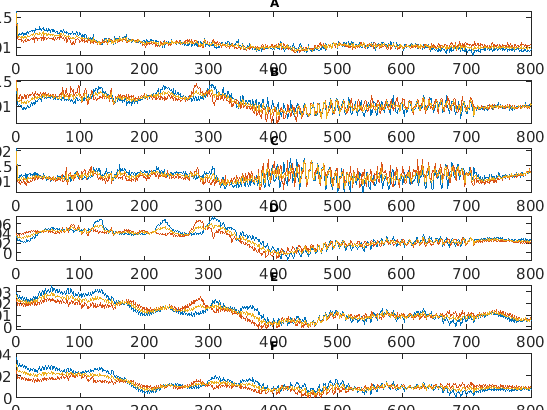

saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_' signal '_all_activity_time_trace.png']);

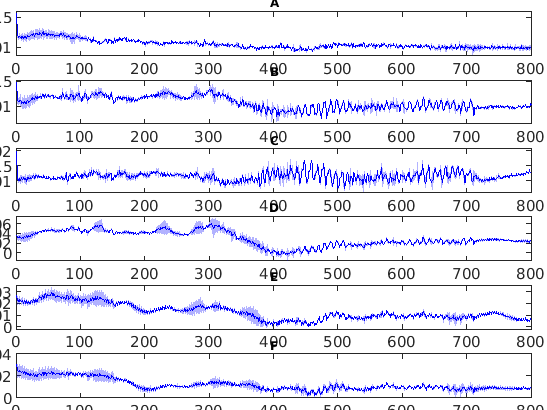


act_Temp_SEM = std(roi_Temp_activities,0,2)/sqrt(size(roi_Temp_activities,2));

figure
for i = 1:length(brain_roi)
    subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0.00, 'Margin', 0.03);
    x = 1:length(roi_Temp_activities(i,j,:));
    x2 = [x, fliplr(x)];
    hold on;
    plot(x,squeeze(block_mean_roi_Temp_activities(i,:)),'b','LineWidth',1);
    alpha_value = 0.3;
%     inBetween = [squeeze(block_mean_roi_Temp_activities(i,:)) + squeeze(act_Temp_SEM(i,:)), transpose(fliplr(transpose(squeeze(block_mean_roi_Temp_activities(i,:)) - squeeze(act_Temp_SEM(i,:)))))];
    inBetween = [squeeze(block_mean_roi_Temp_activities(i,:)) + squeeze(act_Temp_SEM(i,:)), fliplr(squeeze(block_mean_roi_Temp_activities(i,:)) - squeeze(act_Temp_SEM(i,:)))];
    fill(x2, inBetween, 'b', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
    title([brain_roi_name(i)], 'FontSize',6);
    if strcmp(signal, 'df_f')    
        ylim(ylimit);
    end
    hold off;
end
saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_' signal '_mean_activity_time_trace.png']);


% output mean and SEM of neural activity as csv file
% row:brain roi, column:time
all_csvname  = [output_dir Animal '_' signal '_activity_time_trace_all.csv'];
mean_csvname = [output_dir Animal '_' signal '_activity_time_trace_mean.csv'];
SEM_csvname  = [output_dir Animal '_' signal '_activity_time_trace_SEM.csv'];
roi_Temp_activities_reshape = reshape(roi_Temp_activities, [size(roi_Temp_activities,1)*size(roi_Temp_activities,2) size(roi_Temp_activities, 3)]);
writematrix(squeeze(roi_Temp_activities_reshape),all_csvname);
writematrix(squeeze(block_mean_roi_Temp_activities),mean_csvname);
writematrix(squeeze(act_Temp_SEM),SEM_csvname);

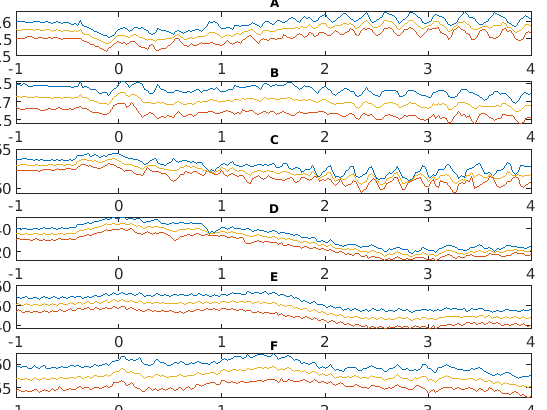

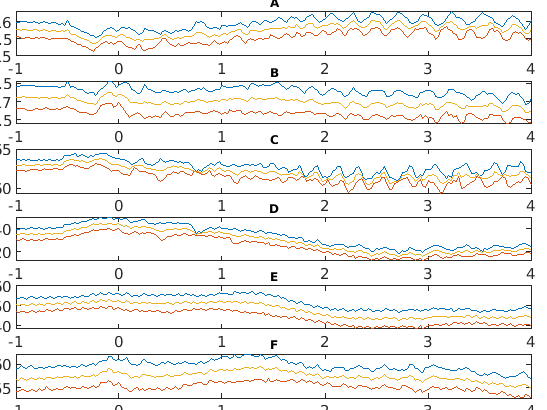

% plot event aligned neural activity of specific brain region
ylimit = [-0.05 0.1]; %[-0.1 0.2]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
addpath([working_directory 'PCA_and_ICA' filesep 'Subaxis']);
for m_event = 1:length(Events)
    figure
    for i = 1:length(brain_roi) 
        subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
        for j = 1:totalBlock
            hold on 
            r = plot(-before/1000:1/fps:after/1000,squeeze(roi_activities(m_event,i,j,:)));
            hold off
        end
        alpha(r,0.1);
        hold on
        b = plot(-before/1000:1/fps:after/1000,squeeze(block_mean_roi_activities(m_event,i,:)));
        title([brain_roi_name(i)], 'FontSize',6);
        if strcmp(signal, 'df_f')        
            ylim(ylimit);  
        end
    end
    saveas(gcf,[output_dir Animal '_' Events{m_event} '_' num2str(ylimit(2)) '_' signal '_all_activity.png']);
end

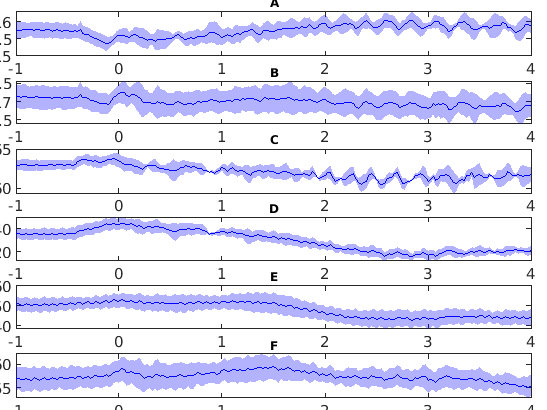

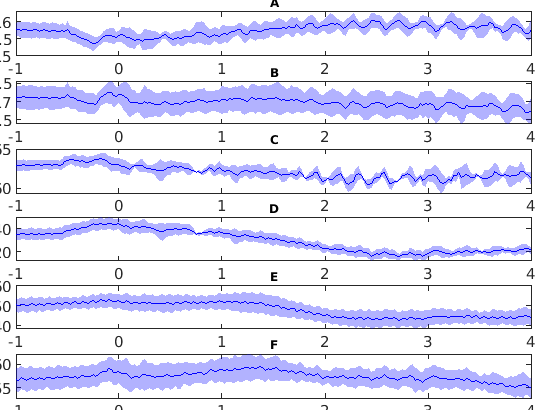


act_SEM = std(roi_activities,0,3)/sqrt(size(roi_activities,3));

for m_event = 1:length(Events)
    figure
    for i = 1:length(brain_roi)
        subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0.00, 'Margin', 0.03);
        x = -before/1000:1/fps:after/1000;
        x2 = [x, fliplr(x)];
        hold on;
        plot(x,squeeze(block_mean_roi_activities(m_event,i,:)),'b','LineWidth',1);
        alpha_value = 0.3;
        inBetween = [transpose(squeeze(block_mean_roi_activities(m_event,i,:)) + squeeze(act_SEM(m_event,i,:))), fliplr(transpose(squeeze(block_mean_roi_activities(m_event,i,:)) - squeeze(act_SEM(m_event,i,:))))];
        fill(x2, inBetween, 'b', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
        title([brain_roi_name(i)], 'FontSize',6);
        if strcmp(signal, 'df_f')        
            ylim(ylimit);  
        end
        hold off;
    end
    saveas(gcf,[output_dir Animal '_' Events{m_event} '_' num2str(ylimit(2)) '_' signal '_mean_activity.png']);
end


% output mean and SEM of neural activity as csv file
% row:brain roi, column:time
for m_event = 1:length(Events)
    all_csvname  = [output_dir Animal '_' Events{m_event} '_' signal '_activity_all.csv'];
    mean_csvname = [output_dir Animal '_' Events{m_event} '_' signal '_activity_mean.csv'];
    SEM_csvname  = [output_dir Animal '_' Events{m_event} '_' signal '_activity_SEM.csv'];
    cor_csvname  = [output_dir Animal '_' Events{m_event} '_' signal '_activity_correlation.csv'];
    roi_activities_reshape = reshape(roi_activities(m_event,:,:,:), [size(roi_activities,2)*size(roi_activities,3) size(roi_activities,4)]);
    writematrix(squeeze(roi_activities_reshape),all_csvname);
    writematrix(squeeze(block_mean_roi_activities(m_event,:,:)),mean_csvname);
    writematrix(squeeze(act_SEM(m_event,:,:)),SEM_csvname);
    writematrix(squeeze(R_roi_act(m_event,:,:)),cor_csvname);
end

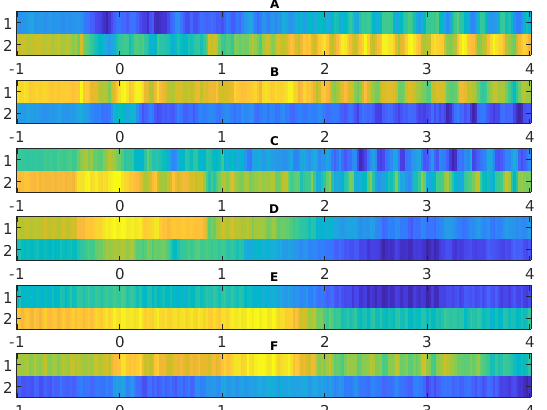

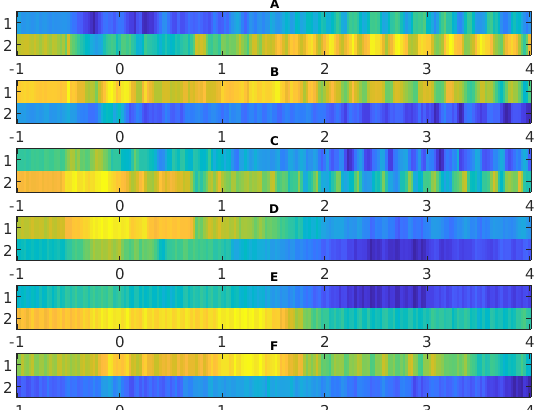

% plot neural activity heatmap of specific brain region
% x:time, y:blocks, color:df/f
climit = [0 0.1]; %[0 0.2];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for m_event = 1:length(Events)
    figure
    set(gcf,'color','w');
    for i = 1:length(brain_roi) 
        cur_roi_act = squeeze(roi_activities(m_event,i,:,:));
        [M,cur_roi_act_i] = max(cur_roi_act,[],2);
        cur_roi_act = cat(2, cur_roi_act_i,cur_roi_act);
        cur_roi_act =   sortrows(cur_roi_act);
        cur_roi_act(:,1) = [];
        subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);      
        clims = climit;        
        image = reshape(cur_roi_act,[size(cur_roi_act,1), size(cur_roi_act,2)]);
        if strcmp(signal, 'df_f') 
            imagesc(-before/1000:1/fps:after/1000,1:size(cur_roi_act,1),image,clims);
        elseif strcmp(signal, 'raw') 
            imagesc(-before/1000:1/fps:after/1000,1:size(cur_roi_act,1),image);
        end
        title([brain_roi_name(i)], 'FontSize',6);
    end
    
    filename = [output_dir Animal, '_' Events{m_event} '_' num2str(clims(2)) '_' signal '_all_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
end

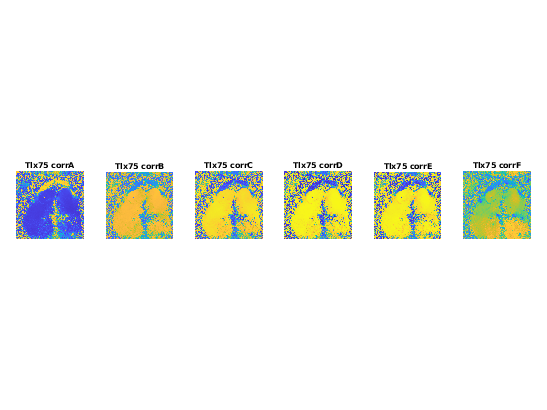

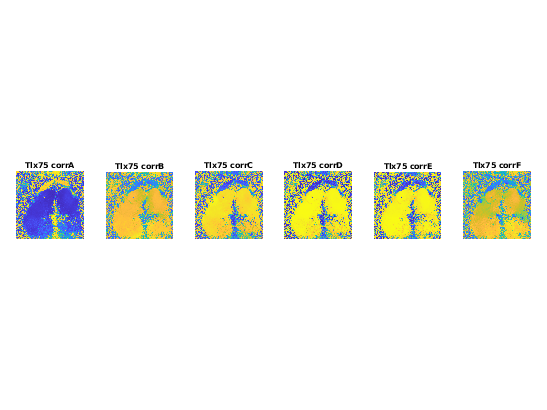

% plot correlation heatmap
for m_event = 1:length(Events)
    figure
    set(gcf,'color','w')
    for i = 1:length(brain_roi)
        subaxis(1,length(brain_roi),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
        clims = [-1 1]; 
        image = R_roi_act(m_event,i,:);
        imagesc(reshape(image,[128 128]),clims)
        axis square
        axis off
        title([Animal ' corr' brain_roi_name(i)], 'FontSize',4);
    end
    saveas(gcf,[output_dir Animal '_' Events{m_event} '_' signal '_activity_correlation_map.png']);
end

% Output tiff images from matrix for visualization written by NY
clear all;
close all;
clc;

CompNum = 40;

Initial = 'KM';
Animal = 'Tlx75';
Date = '230709';
totalBlock = 2;
Block = 1;
Key = 'max';
Events = {'grab','lift'}; % 'Temp'
signal = 'df_f'; % 'df_f' or 'raw'
working_directory = '/home/naohiro/Desktop/Yoshida_analysis/Wide-field-calcium-imaging/';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% for visualizing images after PCA/ICA
cd([working_directory Date filesep Initial '_' Animal filesep 'ICA' filesep 'ICA_40']);

for j = 1:length(Events)
    Events{j} = ['RecICA_', Events{j}];
    if strcmp(signal, 'df_f')
        load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],Events{j},'-mat');
    elseif strcmp(signal, 'raw')     
        load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key '_raw'],Events{j},'-mat');
    end    
    target_var = eval(Events{j});
    max(max(target_var{Block}))
end

ans = 0.0951

ans = 0.0951

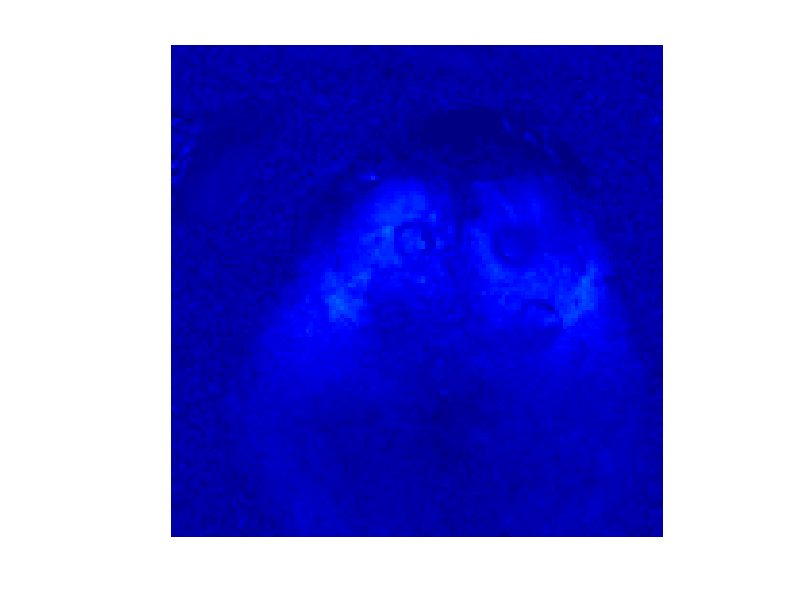

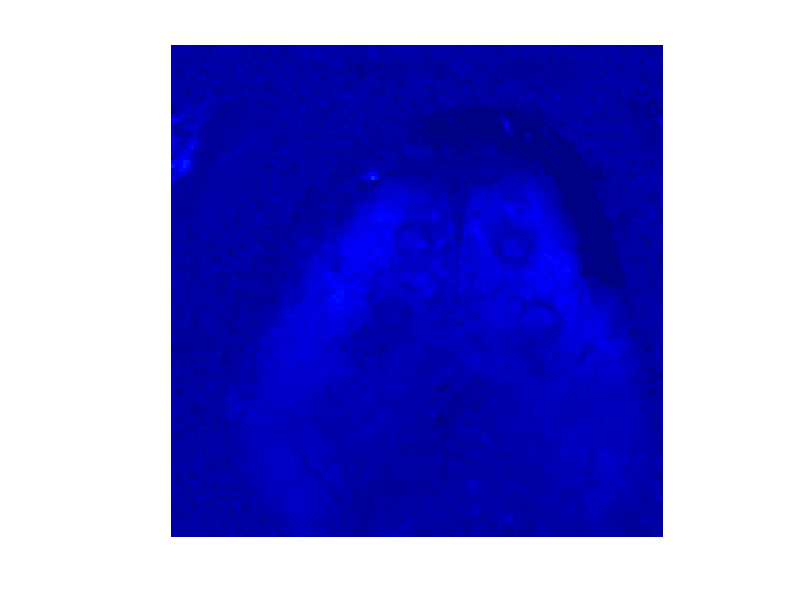

clims = {[0 0.3],[0 0.3]}; %,[0 2000]};%{[0 0.3],[0 0.3]}; % adjust by using max(max(RecICA_Temp{1})) (upper limit)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for j = 1:length(Events)
    mkdir([Events{j} '_out_' Key '_' signal]);
    target_var = eval(Events{j});
    for i = 1:size(target_var{Block},2)
        figure;
        set(gcf,'color','w');
        image = target_var{Block}(:,i);
        imagesc(reshape(image,[128 128]),clims{j});
        colormap jet;
        axis square;
        axis off;
        filename = [Events{j} '_out_' Key '_' signal filesep 'RecICA_' num2str(Block) '_', num2str(i), '.tif'];
        saveas(gcf,filename);
%         axis tight;
%         export_fig([Events{j} '_out_' Key '_' signal filesep 'RecICA_' num2str(Block) '_', num2str(i), '.tif'], '-tif');          
    end
    close all
end

% for visualization of event aligned sequence
Events = {'grab','lift'}; % 'Temp'
fps = 40;
% Specify how many milliseconds before and after the event to plot and how many milliseconds between plots
before = 1000;
after = 4000;
inter = 500;
output_dir = [working_directory Date filesep Initial '_' Animal filesep 'neural_act_outputs' filesep];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% calculate block average RecICA neural activity

mean_RecICAs = cell(1,length(Events));
for j = 1:length(Events)
    Events{j} = ['RecICA_', Events{j}];
    target_var = eval(Events{j});
    mean_RecICAs{j} = zeros(size(target_var{1}));
    for k = 1:totalBlock
        mean_RecICAs{j} = mean_RecICAs{j} + target_var{k};
    end
    mean_RecICAs{j} = mean_RecICAs{j}/totalBlock;
    max(max(mean_RecICAs{j}))
end

ans = 0.0914

ans = 0.0914

clims = {[0 0.1],[0 0.1]}; %{[0 0.2],[0 0.2]}; % adjust by upper limit

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% plot averaged neural activity sequences
addpath([working_directory 'PCA_and_ICA' filesep 'Subaxis']);
for j = 1:length(Events)
    figure;
    set(gcf,'color','w');
    for i = 1:(before+after)/inter   
        subaxis((before+after)/inter/5,5,i, 'Spacing', 0.02, 'Padding', 0, 'Margin', 0.015);
        image = mean(mean_RecICAs{j}(:,inter*(i-1)*fps/1000+1:inter*i*fps/1000),2);
        imagesc(reshape(image,[128 128]),clims{j});
        colormap jet;
        axis square;
        axis off;
        title([Events{j} ' ' num2str(inter*(i-1)-before) ' ms'], 'FontSize',4);
    end
    saveas(gcf,[output_dir Animal '_' Events{j} '_' Key '_' signal '_' num2str(clims{j}(2)) '_RecICA_sequence.png']);
    close all

    % output event aligned averaged neural activity as csv file
    % row:pixel, column:time
    mean_csvname = [output_dir Animal '_' Events{j} '_' signal '_pixel_activity_mean.csv'];
    writematrix(squeeze(mean_RecICAs{j}),mean_csvname);
end

%TODO: have to change for new version
% for visualization of reaching event aligned sequence

fps = 40;
clims = [0 2000];
% timepoints_table = readtable([working_directory Date filesep Initial '_' Animal filesep 'BehaviorRecord.csv'],'NumHeaderLines',1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
events = {'before' 'extend' 'grasp' 'wisdraw' 'after'};
% load behavior data
filename = [working_directory Date filesep Initial '_' Animal filesep 'BehaviorRecord.csv'];
opts = detectImportOptions(filename);
opts.VariableNamesLine = 1;
timepoints_table = readtable(filename, opts); 


behavior_names_csv = {'lift_ms_','grab_ms_','chew_ms_','end_ms_'};
for i_behavior = 1:length(behavior_names_csv)
    behavior_cell = timepoints_table.(behavior_names_csv{i_behavior});
    behavior_timing = cellfun(@str2num,behavior_cell(1:totalBlock));
    if i_behavior == 1
        lift_timing = behavior_timing;
        timepoints = [(behavior_timing-before)*fps/1000 behavior_timing*fps/1000];
    elseif i_behavior == length(behavior_names_csv)
        timepoints = [timepoints behavior_timing*fps/1000 (lift_timing+after)*fps/1000];
    else
        timepoints = [timepoints behavior_timing*fps/1000];
    end
end
% in case there are float (not occured usually)
timepoints = round(timepoints);

for i = 1:totalBlock
    % clip the maxixmum to lift+4sec (ms): table2array(timepoints_table(1:totalBlock,23))*fps/1000+(before+after)*fps/1000
    timepoints(i,timepoints(i,:)>timepoints(i,6)) = timepoints(i,6);
    % set the start of the trail as 1
    timepoints(i,:) = timepoints(i,:) - timepoints(i,1) +1;
end

% plot averaged neural activity sequences
addpath([working_directory 'PCA_and_ICA' filesep 'Subaxis']);
figure;
set(gcf,'color','w');
num_events = length(events);

mean_RecICA_events{num_events} = [];

for i = 1:num_events  
    mean_RecICA_events{i} = zeros(size(RecICA_lift{1},1),1);
    for j = 1:totalBlock
        mean_RecICA_events{i} = mean(RecICA_lift{j}(:,timepoints(j,i):timepoints(j,i+1)),2) + mean_RecICA_events{i};
    end
    mean_RecICA_events{i} = mean_RecICA_events{i}/totalBlock;
    subaxis(1,num_events,i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
    image = mean_RecICA_events{i};
    imagesc(reshape(image,[128 128]),clims);
    colormap jet;
    axis square;
    axis off;
    title(['RecICA ' events(i)], 'FontSize',4);
end
saveas(gcf,[output_dir Animal '_' Key '_' signal '_' num2str(clims(2)) '_RecICA_reaching_events.png']);
close all

% output event aligned averaged neural activity as csv file
% row:pixel, column:event
mean_RecICA_events_reshape = cell2mat(mean_RecICA_events);
mean_csvname = [output_dir Animal '_' signal '_pixel_reaching_event_aligned_activity.csv'];
writematrix(squeeze(mean_RecICA_events_reshape),mean_csvname);